# Modeling Subarray Failures in a Sensor Array

This example shows how to model subarray failures in a sensor array and how to see the impact of failed subarrays on the array pattern

rng("default");
c = 3e8; freq = 60e9;

## Subarrays

You can model and visualize subarrays. Next is an example of contiguous subarrays. Each subarry is a 5x5 URA The subarrays are arrainged as a 3x3 matrix 

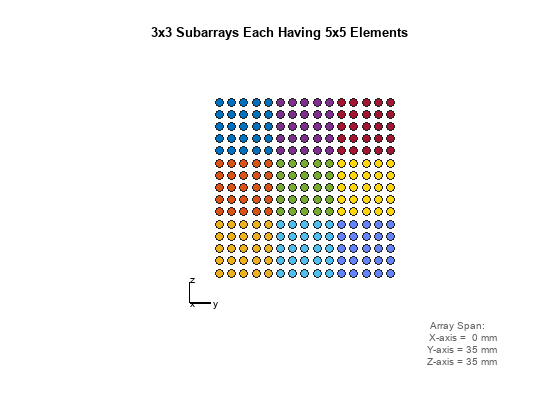

iURA = phased.URA(5);
iURA.ElementSpacing = [0.0025, 0.0025];

subURA = phased.ReplicatedSubarray("Subarray",iURA,...
                               "Layout","Rectangular",...
                               "GridSize",[3 3],"GridSpacing","Auto");


viewArray(subURA,"Title","3x3 Subarrays Each Having 5x5 Elements"); 


sURA = phased.URA([15 15]); % This creates a 15x15 URA without subarrays 
                            % for comparison purposes

sURA.ElementSpacing = [.0025, .0025];

Compare the response of the array with a failed subarray to the ideal array.

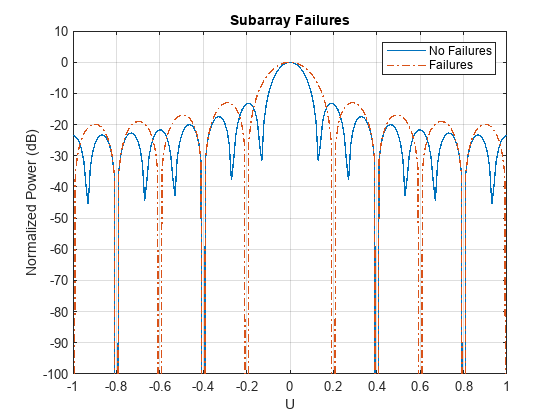

% Overlay responses
clf;

pattern(sURA,freq,-1:0.01:1,0,"PropagationSpeed",c,...
    "CoordinateSystem","uv","Type","powerdb");
ylim([-40 2]);
hold on


pattern(subURA,freq,-1:0.01:1,0,"PropagationSpeed",c,...
    "CoordinateSystem","uv","Type","powerdb", ...
    "weights",[1 1 1 1 1 1 0 0 0]');       % The 0 simulates a failed
% subarray in subarray 6
% SA1 SA4 SA7
% SA2 SA5 SA8
% SA3 SA6 SA9

title("Subarray Failures");
legend("No Failures","Failures","Location","NorthEast")
ah = gca;
ah.Children(1).LineStyle = "-.";
ah.Children(1).LineWidth = 1;
ah.Children(2).LineWidth = 1;

*Copyright 2010-2013 The MathWorks, Inc.*